% Section a
syms z n Y
X = simplify(ztrans((0.8^n)*heaviside(n) + (0.8^(n-1))*heaviside(n-1)));
Y1 = z^(-1)*Y;
Y2 = z^(-2)*Y;
G = Y + 1.5*Y1 + 0.5*Y2 - X;
SOL1 = solve(G,Y);
y1 = iztrans(SOL1,n)

$$y1 = \frac{8\,{\left(\frac{4}{5}\right)}^{n}}{13}-\frac{3\,{\left(-\frac{1}{2}\right)}^{n}}{26}$$

y1_plot = subs(y1,n,[0:20]);
k = 5

k = 5

y1_validation = subs(y1,n,k)+1.5*subs(y1,n,k-1)+0.5*subs(y1,n,k-2) - subs((0.8^n)*heaviside(n),n,k) - subs((0.8^n)*heaviside(n),n,k-1)

$$y1\_validation = 0$$

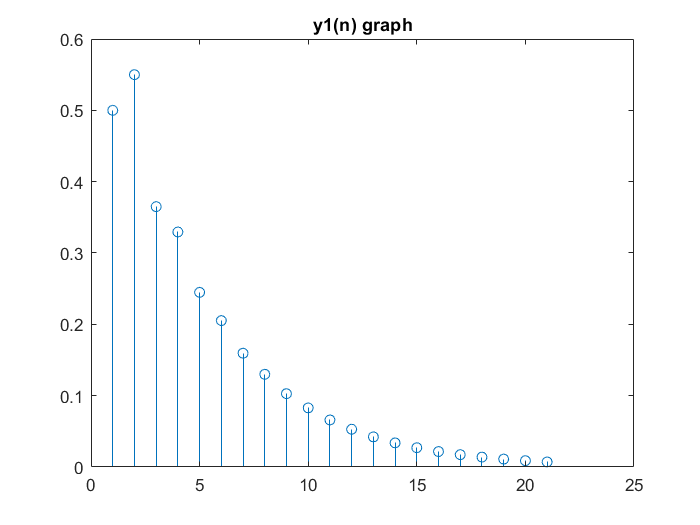

stem(y1_plot)
title("y1(n) graph")

% Section b
syms z n y
X = simplify(ztrans((0.8^n)*heaviside(n) + (0.8^(n-1))*heaviside(n-1)));
Y1 = z^(-1)*Y;
Y2 = z^(-2)*Y;
G = Y - Y1 - X;
SOL2 = solve(G,Y);
y2 = iztrans(SOL2,n)

$$y2 = \frac{\delta_{n,0}}{2}-9\,{\left(\frac{4}{5}\right)}^{n}+9$$

y2_plot = subs(y2,n,[0:20]);
k = 2

k = 2

y2_validation = subs(y2,n,k)-subs(y2,n,k-1) - subs((0.8^n)*heaviside(n),n,k) - subs((0.8^n)*heaviside(n),n,k-1)

$$y2\_validation = 0$$

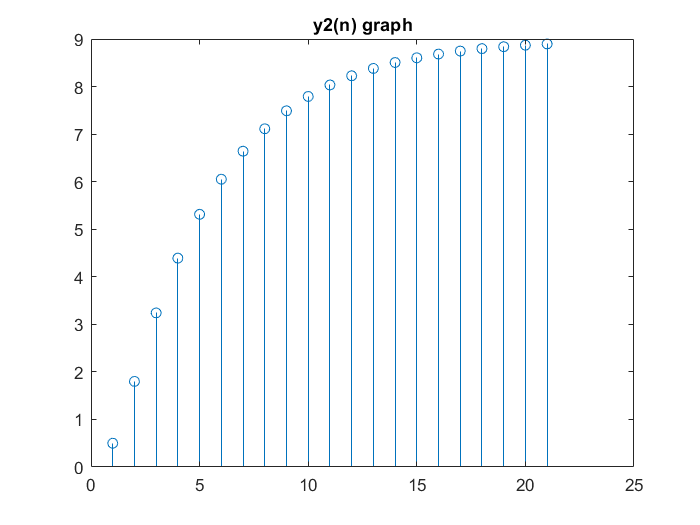

stem(y2_plot)
title("y2(n) graph")